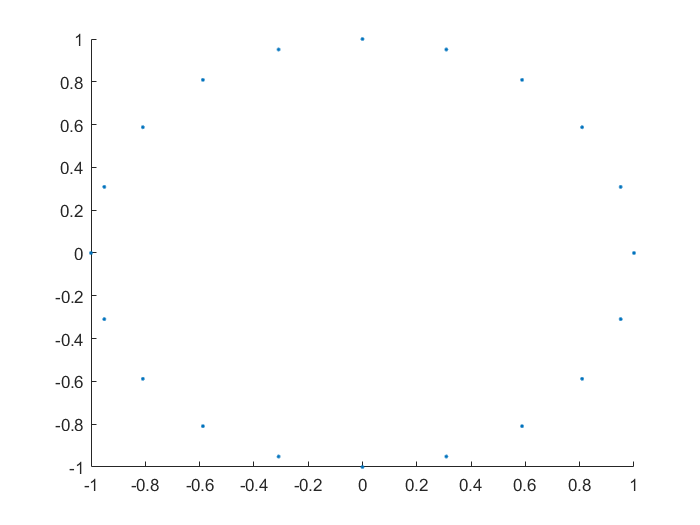

count = 20;
theta = 0:(2*pi/count):2*pi;
% theta(end)=[];
Points = [cos(theta'),sin(theta')];
Normals = Points;
scatter(Points(:,1),Points(:,2),'.');

n = length(theta);

k = 7*ones(n,1);
% k(5:9)=4*ones(5,1);
% k(11:13)=4*ones(3,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
% 计算各点支撑半径
SupportSizes = zeros(n,1);
distlist=SupportSizes;
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
    distlist(i)=dists(2);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);


% 设置拟合系数
ApproxArgs = zeros(n,1);


c=1;
for i=1:n
    ApproxArgs(i) =c;
end


% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end

        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
        
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
f = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
%测试点误差
res = 1000;
theta = 0:(2*pi/res):2*pi;
F1=zeros(length(theta),1);
respoints = [cos(theta)',sin(theta)'];
for j=1:length(theta)
    F1(j)=f(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F1))

Maxe2 = 9.5521e-04

Meane2=mean(abs(F1))

Meane2 = 1.9369e-04

k = 7*ones(n,1);
% k(5:9)=4*ones(5,1);
% k(11:13)=4*ones(3,1);
s = -0.5;
% 生成kd树
kdtree = KDTreeSearcher(Points);
% 计算各点支撑半径
SupportSizes = zeros(n,1);
distlist=SupportSizes;
for i=1:n
    [indices,dists] = knnsearch(kdtree, Points(i,:), 'K', k(i));
    SupportSizes(i) = max(dists);
    distlist(i)=dists(2);
end
maxSupportSize = max(SupportSizes);
% 生成局部坐标系，各点二次曲线
[Bases,Hparas,Err] = CalHParas(Points,Normals,k,kdtree);


% 设置拟合系数
ApproxArgs = zeros(n,1);


maxerr=max(Err);
minerr=min(Err);
Err=(Err-minerr)/(maxerr-minerr);
maxerr=1;minerr=0;
meanerr=mean(Err);

maxd=max(distlist);
mind=min(distlist);
distlist=(distlist-mind)/(maxd-mind);

var=sum((Err-meanerr).^2)/n;

meand=mean(distlist);
vard=sum((distlist-meand).^2)/n;

en=0.9;
if(meanerr>en)
    c=5^(-meanerr/en-1);
else
    c=5^(-meanerr/en+1);
end
c=1;
for i=1:n
    ApproxArgs(i) =c;
    if((distlist(i)-meand)^2>3*vard)
        x=sqrt((distlist(i)-meand)^2)/(3*vard);
        if((distlist(i)-meand)<0)
            ApproxArgs(i)=ApproxArgs(i)*(x);
        else
            ApproxArgs(i)=ApproxArgs(i)*(1/x);
        end
    elseif((Err(i)-meanerr)^2>3*var)
        x=sqrt(Err(i)-meanerr)^2/(3*var);
        if(Err(i)-meanerr>0)
            ApproxArgs(i)=ApproxArgs(i)*(1/x);
        else
            ApproxArgs(i)=ApproxArgs(i)*(x);
        end
    end
    %ApproxArgs(i) = 1;
end


% ApproxArgs([2,20])=0.5;
% ApproxArgs([3:19])=1;
% ApproxArgs([1,21])=2;
% 
% for i=1:n
%         ApproxArgs(i)=1;
% end
% 计算C值
C = zeros(n,1);
for i=1:n
    [indices,dists] = rangesearch(kdtree, Points(i,:), maxSupportSize);
    indices = indices{1};
    dists = dists{1};
    valsum = 0;
    rbfsum = 0;
    H = Calh(Points(i,1),Points(i,2),Points(indices,:),Bases(indices,:),Hparas(indices));
    for j=1:length(indices)
        if dists(j)>=SupportSizes(indices(j))
            continue
        end
        if dists(j)<1e-7 && ApproxArgs(indices(j))<1e-7 
            valsum = C(indices(j))+H(j);
            rbfsum = 1;
            break;
        end
        value = rbf(dists(j)/SupportSizes(indices(j)),ApproxArgs(indices(j)),s);
        
        valsum = valsum - H(j)*value;
        rbfsum = rbfsum + value;
    end
    C(i) = valsum/rbfsum;
end

% % 画隐曲线
g = @(x,y)(CalRBFV(x,y,kdtree,Points,Bases,Hparas,maxSupportSize,SupportSizes,ApproxArgs,s,C,1));
% area = [-1,1,-1,1];
% fp = fimplicit(f, area);
% % 
% hold on;
% scatter(Points(:,1),Points(:,2),'*');
% hold off;

%测试点误差
res = 1000;
theta = 0:(2*pi/res):2*pi;
F2=zeros(length(theta),1);
respoints = [cos(theta)',sin(theta)'];
for j=1:length(theta)
    F2(j)=g(respoints(j,1),respoints(j,2));
end
Maxe2=max(abs(F2))

Maxe2 = 2.8032e-04

Meane2=mean(abs(F2))

Meane2 = 1.0552e-04

% area = [-1,1,-1,1];
% h=@(x,y)(x^2+y^2-1);
% gp1=fimplicit(h, area);

% hold on
% fp1=fimplicit(f, area);

% hold on
% fp2=fimplicit(g, area);

% hold on
% scatter(Points(:,1),Points(:,2),'*');